% function [theta] = redundancy_resolution(T_sb,T_sd)

clear
clc

L=[100 265 360 360 175];
omega=[
    0,0,1;%1
    0,1,0;%2
    -1,0,0;%3
    0,0,-1;%4
    1,0,0;%5
    0,0,1;%6
    1,0,0;%7
    0,0,1;%8
    ];
q=[
    [-L(1),0,0];%1
    [0,L(2),0];%2
    [0,L(2),0];%3
    [0,L(2),-L(3)];%4
    [0,L(2),-L(3)];%5
    [0,L(2),-L(3)];%6
    [0,L(2),-L(3)-L(4)];%7
    [0,L(2),-L(3)-L(4)-L(5)];%8
    ];
home=[
    1 0 0 0;
    0 1 0 L(2);
    0 0 1 -L(3)-L(4)-L(5);
    0 0 0 1
    ];
%testing ---------------
T_sb=[1 0 0 0;
    0 1 0 L(2);
    0 0 1 -L(3)-L(4)-L(5);
    0 0 0 1];
T_sd=[1 0 0 0;
    0 1 0 L(3);
    0 0 1 L(4);
    0 0 0 L(5)];
%end of testing --------

%initial guess, setting error criteria
theta=[pi/8 pi/8 pi/8 pi/8 pi/8 pi/8 pi/8 pi/8]

theta =     0.3927    0.3927    0.3927    0.3927    0.3927    0.3927    0.3927    0.3927


J_min_norm =   -29.1350
    6.1524
   22.4389
  -12.4468
   28.1601
   11.0911
  -12.9484
    2.3897


k_0 = 2.0000e-06

q_0 =    74.7085
   74.7085
   74.7085
   74.7085
   74.7085
   74.7085
   74.7085
   74.7085


I_n =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol =    18.4243
    9.3187
    1.0179
   50.4660
   15.6683
   64.1900
   -1.8754
  -38.7820


theta_delta =   -10.7107
   15.4711
   23.4568
   38.0192
   43.8284
   75.2811
  -14.8238
  -36.3923


theta =   -10.3180   15.8638   23.8495   38.4119   44.2211   75.6738  -14.4311  -35.9996


J_min_norm =   -17.6037
  -12.0989
   14.7182
   11.1831
   55.4459
   -2.7379
  -32.2918
    9.6338


k_0 = 2.0000e-06

q_0 =   166.8521
  166.8521
  166.8521
  166.8521
  166.8521
  166.8521
  166.8521
  166.8521


I_n =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol =    10.5699
  153.2785
   -5.2181
   79.3777
   27.1485
  238.0900
   -3.1823
   28.3934


theta_delta =    -7.0338
  141.1796
    9.5002
   90.5608
   82.5944
  235.3521
  -35.4741
   38.0272


theta =   -17.3517  157.0434   33.3497  128.9727  126.8155  311.0259  -49.9052    2.0276


J_min_norm =     5.0812
   -4.7996
  -12.3274
   -2.9623
   21.8758
   -5.0839
    9.0102
    7.7735


k_0 = 2.0000e-06

q_0 =    73.9043
   73.9043
   73.9043
   73.9043
   73.9043
   73.9043
   73.9043
   73.9043


I_n =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol =    64.5615
   40.2348
    6.2399
   79.1872
   -9.1011
   18.2186
  -17.9183
   81.0086


theta_delta =    69.6426
   35.4352
   -6.0875
   76.2249
   12.7748
   13.1348
   -8.9082
   88.7821


theta =    52.2909  192.4786   27.2622  205.1976  139.5902  324.1606  -58.8133   90.8097


J_min_norm =     1.5356
  -14.6386
   11.8466
   -3.1633
  -11.6279
    0.0253
   -2.9494
   -9.3325


k_0 = 2.0000e-06

q_0 =   137.6218
  137.6218
  137.6218
  137.6218
  137.6218
  137.6218
  137.6218
  137.6218


I_n =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol =    45.5298
   55.2467
   44.8680
  113.0087
   -0.3952
  -12.3841
  -23.2722
  -52.7021


theta_delta =    47.0654
   40.6081
   56.7146
  109.8454
  -12.0231
  -12.3589
  -26.2215
  -62.0346


theta =    99.3563  233.0867   83.9768  315.0430  127.5671  311.8018  -85.0349   28.7751


J_min_norm =     8.1130
   17.2823
   -7.9292
    7.2747
   -9.2552
   -1.2311
    6.5773
    5.9435


k_0 = 2.0000e-06

q_0 =   115.4053
  115.4053
  115.4053
  115.4053
  115.4053
  115.4053
  115.4053
  115.4053


I_n =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol =   -95.3332
   44.9226
   51.8247
   51.1122
   69.6611
  106.6849
   53.0247
   77.9843


theta_delta =   -87.2202
   62.2049
   43.8955
   58.3869
   60.4059
  105.4537
   59.6020
   83.9278


theta =    12.1361  295.2916  127.8722  373.4299  187.9730  417.2555  -25.4329  112.7029


J_min_norm =    18.6909
    2.8018
   16.0598
   -5.2599
  -34.7563
   -2.9425
  -16.5582
    1.7457


k_0 = 2.0000e-06

q_0 =    57.4684
   57.4684
   57.4684
   57.4684
   57.4684
   57.4684
   57.4684
   57.4684


I_n =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol =    -5.7879
  -18.0131
    8.2409
   45.5650
   -3.8538
   26.5552
   -9.2506
   32.6480


theta_delta =    12.9030
  -15.2113
   24.3007
   40.3050
  -38.6102
   23.6127
  -25.8088
   34.3937


theta =    25.0391  280.0803  152.1729  413.7350  149.3628  440.8682  -51.2417  147.0965


J_min_norm =     8.5064
   -1.3534
   -1.9139
    9.1376
    1.6899
   -0.1354
  -15.6074
    4.2726


k_0 = 2.0000e-06

q_0 =   106.1984
  106.1984
  106.1984
  106.1984
  106.1984
  106.1984
  106.1984
  106.1984


I_n =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol =    -1.6513
  110.2199
   29.1580
   67.0007
    0.5065
  -53.1418
   31.5393
   21.2966


theta_delta =     6.8550
  108.8665
   27.2441
   76.1384
    2.1964
  -53.2771
   15.9319
   25.5692


theta =    31.8941  388.9468  179.4170  489.8733  151.5592  387.5911  -35.3098  172.6657


J_min_norm =     3.2386
   -3.3045
   -5.5759
   -3.3329
   -3.8775
    3.1234
    4.4367
    4.0126


k_0 = 2.0000e-06

q_0 =   321.5635
  321.5635
  321.5635
  321.5635
  321.5635
  321.5635
  321.5635
  321.5635


I_n =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol =   241.2985
   90.8666
  264.6329
   20.2131
  298.8729
  411.5002
  -78.9715
  320.4062


theta_delta =   244.5371
   87.5621
  259.0570
   16.8802
  294.9954
  414.6236
  -74.5348
  324.4189


theta =   276.4312  476.5089  438.4741  506.7535  446.5546  802.2147 -109.8446  497.0846


J_min_norm =    18.5212
   -4.8142
   47.4215
   71.4873
  -49.8745
  228.8755
  -19.1256
  162.5197


k_0 = 2.0000e-06

q_0 = 8×1
   12.9337
   12.9337
   12.9337
   12.9337
   12.9337
   12.9337
   12.9337
   12.9337


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    0.8675
   -2.5354
    0.5763
    0.7341
    0.4492
   -0.8836
    0.7791
    0.8088


theta_delta = 8×1
   19.3888
   -7.3496
   47.9978
   72.2214
  -49.4253
  227.9919
  -18.3465
  163.3285


theta = 1×8
1.0e+03 *

    0.2958    0.4692    0.4865    0.5790    0.3971    1.0302   -0.1282    0.6604


J_min_norm = 8×1
    0.3133
   10.0851
   -3.1487
    6.0257
   -2.5781
   -1.6604
   -6.8573
    0.6483


k_0 = 2.0000e-06

q_0 = 8×1
  225.1376
  225.1376
  225.1376
  225.1376
  225.1376
  225.1376
  225.1376
  225.1376


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  171.8662
  -77.1473
   34.0928
  132.2693
   94.6353
  213.3877
  -88.0455
   44.8434


theta_delta = 8×1
  172.1795
  -67.0621
   30.9440
  138.2951
   92.0571
  211.7273
  -94.9028
   45.4917


theta = 1×8
1.0e+03 *

    0.4680    0.4021    0.5174    0.7173    0.4892    1.2419   -0.2231    0.7059


J_min_norm = 8×1
  -14.5872
   20.2066
    3.5539
   21.3420
   -0.7267
    3.3979
   -5.6500
    3.0501


k_0 = 2.0000e-06

q_0 = 8×1
   39.8290
   39.8290
   39.8290
   39.8290
   39.8290
   39.8290
   39.8290
   39.8290


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   37.8462
    0.3036
   10.4639
   17.1895
  -10.2313
   57.6272
   18.3548
   13.8831


theta_delta = 8×1
   23.2590
   20.5102
   14.0178
   38.5314
  -10.9580
   61.0251
   12.7048
   16.9332


theta = 1×8
1.0e+03 *

    0.4913    0.4226    0.5314    0.7558    0.4782    1.3030   -0.2104    0.7228


J_min_norm = 8×1
  -19.2056
    7.8026
   34.1933
  -13.0112
   -5.2396
  -14.2839
    6.4429
    0.3960


k_0 = 2.0000e-06

q_0 = 8×1
   87.3618
   87.3618
   87.3618
   87.3618
   87.3618
   87.3618
   87.3618
   87.3618


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -44.6765
  -17.9548
   38.4856
   49.9920
   53.0793
   98.9541
   43.8378
   64.8442


theta_delta = 8×1
  -63.8821
  -10.1522
   72.6789
   36.9808
   47.8397
   84.6702
   50.2808
   65.2402


theta = 1×8
1.0e+03 *

    0.4274    0.4125    0.6041    0.7928    0.5261    1.3876   -0.1601    0.7881


J_min_norm = 8×1
    3.4375
   16.7989
   10.3936
   15.7639
   11.2978
    1.0073
    4.6427
    0.0375


k_0 = 2.0000e-06

q_0 = 8×1
   88.1234
   88.1234
   88.1234
   88.1234
   88.1234
   88.1234
   88.1234
   88.1234


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -6.5020
    8.5844
  -11.6106
    0.4359
   -4.9501
   71.2663
   -5.7724
   77.0441


theta_delta = 8×1
   -3.0645
   25.3833
   -1.2170
   16.1998
    6.3478
   72.2736
   -1.1297
   77.0816


theta = 1×8
1.0e+03 *

    0.4243    0.4378    0.6029    0.8090    0.5324    1.4599   -0.1612    0.8652


J_min_norm = 8×1
   -5.8989
   -6.1651
    2.9286
    6.3602
    5.2008
   -8.8695
   -1.4359
   -0.9321


k_0 = 2.0000e-06

q_0 = 8×1
  236.6116
  236.6116
  236.6116
  236.6116
  236.6116
  236.6116
  236.6116
  236.6116


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   77.2054
   37.5203
  130.8792
  -60.2747
   18.1389
  -71.6869
   45.9849
  -24.3285


theta_delta = 8×1
   71.3065
   31.3553
  133.8078
  -53.9145
   23.3396
  -80.5564
   44.5490
  -25.2606


theta = 1×8
1.0e+03 *

    0.4956    0.4692    0.7367    0.7551    0.5558    1.3793   -0.1167    0.8399


J_min_norm = 8×1
   32.3876
   48.9042
   -2.5466
  -48.8850
    3.9445
  112.9743
    4.7406
   10.3195


k_0 = 2.0000e-06

q_0 = 8×1
   11.4146
   11.4146
   11.4146
   11.4146
   11.4146
   11.4146
   11.4146
   11.4146


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -1.2314
    9.8476
   -2.3242
   12.9799
    0.0629
    1.2176
    0.7921
    4.3931


theta_delta = 8×1
   31.1563
   58.7518
   -4.8709
  -35.9051
    4.0074
  114.1919
    5.5327
   14.7126


theta = 1×8
1.0e+03 *

    0.5268    0.5279    0.7318    0.7192    0.5598    1.4935   -0.1112    0.8546


J_min_norm = 8×1
   -7.3412
    3.8517
    4.3622
    5.4358
  -14.5306
   -5.3493
   -0.4654
  -11.8743


k_0 = 2.0000e-06

q_0 = 8×1
  185.2114
  185.2114
  185.2114
  185.2114
  185.2114
  185.2114
  185.2114
  185.2114


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   47.5191
   66.4126
  -17.5292
  149.8200
  -23.3745
  194.9470
  -39.0994
   -3.3791


theta_delta = 8×1
   40.1778
   70.2643
  -13.1670
  155.2558
  -37.9051
  189.5976
  -39.5647
  -15.2535


theta = 1×8
1.0e+03 *

    0.5670    0.5982    0.7187    0.8744    0.5219    1.6831   -0.1507    0.8394


J_min_norm = 8×1
    4.9469
    4.5317
  -14.6026
    7.6616
  -12.2157
    1.0599
    5.6014
    6.3443


k_0 = 2.0000e-06

q_0 = 8×1
  121.9934
  121.9934
  121.9934
  121.9934
  121.9934
  121.9934
  121.9934
  121.9934


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -13.1016
  -43.6528
    4.1956
   94.4699
   52.1929
   67.8093
  -32.9089
   55.1920


theta_delta = 8×1
   -8.1547
  -39.1211
  -10.4070
  102.1314
   39.9772
   68.8691
  -27.3075
   61.5363


theta = 1×8
1.0e+03 *

    0.5588    0.5591    0.7083    0.9765    0.5618    1.7520   -0.1780    0.9009


J_min_norm = 8×1
    0.2825
   12.7136
   12.1173
   10.7711
    0.7927
  -25.9178
  -13.3267
   -7.1384


k_0 = 2.0000e-06

q_0 = 8×1
   84.8771
   84.8771
   84.8771
   84.8771
   84.8771
   84.8771
   84.8771
   84.8771


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -1.5068
    2.7226
   -2.7079
    0.2701
    0.4490
    0.7034
   -2.7663
    3.2608


theta_delta = 8×1
   -1.2243
   15.4362
    9.4094
   11.0412
    1.2417
  -25.2144
  -16.0930
   -3.8777


theta = 1×8
1.0e+03 *

    0.5576    0.5745    0.7177    0.9876    0.5631    1.7268   -0.1941    0.8970


J_min_norm = 8×1
    6.7893
   -5.5059
   -5.3205
    8.3540
   -1.8128
  -12.0785
    8.2055
   -2.7368


k_0 = 2.0000e-06

q_0 = 8×1
   33.2293
   33.2293
   33.2293
   33.2293
   33.2293
   33.2293
   33.2293
   33.2293


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -11.8587
   15.5403
    7.1555
   19.5754
   -9.9591
    3.1674
    6.9984
   -1.2398


theta_delta = 8×1
   -5.0694
   10.0344
    1.8349
   27.9294
  -11.7719
   -8.9111
   15.2039
   -3.9766


theta = 1×8
1.0e+03 *

    0.5525    0.5846    0.7195    1.0155    0.5513    1.7179   -0.1789    0.8930


J_min_norm = 8×1
   -4.3147
    4.0624
   -8.8808
    6.0232
    5.5852
    0.7340
   -5.0074
   -3.0649


k_0 = 2.0000e-06

q_0 = 8×1
  238.4707
  238.4707
  238.4707
  238.4707
  238.4707
  238.4707
  238.4707
  238.4707


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   94.4059
   52.0584
  -70.4742
  -63.9384
   79.9670
  223.3552
   -6.1547
  223.9222


theta_delta = 8×1
   90.0912
   56.1207
  -79.3551
  -57.9152
   85.5523
  224.0892
  -11.1621
  220.8573


theta = 1×8
1.0e+03 *

    0.6426    0.6407    0.6401    0.9576    0.6369    1.9420   -0.1901    1.1139


J_min_norm = 8×1
   -3.3379
   -4.9644
    2.6011
   -4.0714
    8.9072
    5.6307
  -14.1459
    4.9654


k_0 = 2.0000e-06

q_0 = 8×1
  181.1068
  181.1068
  181.1068
  181.1068
  181.1068
  181.1068
  181.1068
  181.1068


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -4.9232
  -61.2594
  -37.0919
   69.0466
    3.0304
   27.6876
   28.4595
   55.7321


theta_delta = 8×1
   -8.2611
  -66.2238
  -34.4908
   64.9752
   11.9376
   33.3184
   14.3136
   60.6975


theta = 1×8
1.0e+03 *

    0.6343    0.5745    0.6057    1.0226    0.6488    1.9753   -0.1758    1.1746


J_min_norm = 8×1
    6.6426
   14.9091
   -3.9016
   15.3308
    9.8250
    1.0165
    2.2530
   -2.0355


k_0 = 2.0000e-06

q_0 = 8×1
  127.6892
  127.6892
  127.6892
  127.6892
  127.6892
  127.6892
  127.6892
  127.6892


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -67.7312
    7.3070
   73.9634
   -2.5014
   72.0685
  -21.9248
   50.7729
   64.9875


theta_delta = 8×1
  -61.0886
   22.2161
   70.0617
   12.8295
   81.8935
  -20.9083
   53.0259
   62.9520


theta = 1×8
1.0e+03 *

    0.5732    0.5967    0.6757    1.0354    0.7307    1.9544   -0.1227    1.2375


J_min_norm = 8×1
   -2.8009
   -3.6553
  -13.8542
    3.1142
    3.0336
   -8.0518
   -9.7417
    3.5557


k_0 = 2.0000e-06

q_0 = 8×1
  216.0946
  216.0946
  216.0946
  216.0946
  216.0946
  216.0946
  216.0946
  216.0946


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   44.6604
   53.9428
  -42.0327
  -84.4897
   36.5643
  118.6006
  -23.5184
  173.7991


theta_delta = 8×1
   41.8595
   50.2874
  -55.8869
  -81.3756
   39.5978
  110.5488
  -33.2601
  177.3549


theta = 1×8
1.0e+03 *

    0.6151    0.6470    0.6198    0.9540    0.7703    2.0649   -0.1560    1.4149


J_min_norm = 8×1
    3.1962
    7.8520
    3.2617
    4.7188
   11.7948
  -12.7868
   10.3264
    3.1917


k_0 = 2.0000e-06

q_0 = 8×1
  123.4913
  123.4913
  123.4913
  123.4913
  123.4913
  123.4913
  123.4913
  123.4913


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    5.7182
   22.8684
   -1.8645
  -23.7475
    2.8100
    8.7893
    1.9197
   -6.3530


theta_delta = 8×1
    8.9144
   30.7204
    1.3972
  -19.0287
   14.6048
   -3.9975
   12.2461
   -3.1613


theta = 1×8
1.0e+03 *

    0.6240    0.6777    0.6212    0.9350    0.7849    2.0609   -0.1438    1.4117


J_min_norm = 8×1
  -12.9632
   -4.9201
   -8.9294
   -3.2200
   14.7985
    3.0115
   -5.6769
   -4.1084


k_0 = 2.0000e-06

q_0 = 8×1
  181.5185
  181.5185
  181.5185
  181.5185
  181.5185
  181.5185
  181.5185
  181.5185


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   27.6236
  -71.9401
    3.2110
  206.2973
   39.2400
   95.9477
  -13.2547
   60.3130


theta_delta = 8×1
   14.6604
  -76.8602
   -5.7185
  203.0772
   54.0385
   98.9592
  -18.9316
   56.2046


theta = 1×8
1.0e+03 *

    0.6387    0.6008    0.6155    1.1381    0.8389    2.1599   -0.1627    1.4679


J_min_norm = 8×1
   10.4974
  -18.8020
    6.1973
  -93.5784
   13.0675
   56.0508
    0.1343
   45.7036


k_0 = 2.0000e-06

q_0 = 8×1
    9.8763
    9.8763
    9.8763
    9.8763
    9.8763
    9.8763
    9.8763
    9.8763


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -0.1763
   -4.1463
    4.9479
    1.4184
   -0.1199
    0.9092
    6.4463
   -0.5316


theta_delta = 8×1
   10.3210
  -22.9483
   11.1452
  -92.1599
   12.9476
   56.9600
    6.5806
   45.1719


theta = 1×8
1.0e+03 *

    0.6490    0.5779    0.6267    1.0459    0.8519    2.2168   -0.1561    1.5131


J_min_norm = 8×1
    3.9735
   -2.7818
   18.8051
   -3.8979
    4.3417
   -4.5806
   -5.6151
   24.9799


k_0 = 2.0000e-06

q_0 = 8×1
   63.4654
   63.4654
   63.4654
   63.4654
   63.4654
   63.4654
   63.4654
   63.4654


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   30.6196
   20.9009
    4.0185
   26.4876
  -10.4677
  -33.8995
   51.0234
    5.6373


theta_delta = 8×1
   34.5931
   18.1191
   22.8236
   22.5896
   -6.1260
  -38.4801
   45.4084
   30.6172


theta = 1×8
1.0e+03 *

    0.6836    0.5960    0.6495    1.0685    0.8458    2.1784   -0.1107    1.5437


J_min_norm = 8×1
  -10.6290
  -11.1807
   13.5805
    2.1637
    7.2280
  -25.6074
   -4.8018
  -25.3234


k_0 = 2.0000e-06

q_0 = 8×1
   55.9193
   55.9193
   55.9193
   55.9193
   55.9193
   55.9193
   55.9193
   55.9193


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -3.0715
   54.6081
   12.9999
   55.8457
    2.4662
   -0.2173
   37.4799
  -17.2614


theta_delta = 8×1
  -13.7005
   43.4274
   26.5803
   58.0093
    9.6942
  -25.8246
   32.6780
  -42.5847


theta = 1×8
1.0e+03 *

    0.6699    0.6394    0.6761    1.1265    0.8554    2.1525   -0.0780    1.5011


J_min_norm = 8×1
  -11.1606
   -2.3342
   -9.6430
   -2.4893
    6.3413
   -5.1312
    6.1805
   -1.0285


k_0 = 2.0000e-06

q_0 = 8×1
  180.3574
  180.3574
  180.3574
  180.3574
  180.3574
  180.3574
  180.3574
  180.3574


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   43.8258
  -25.5849
   57.1977
  -17.7657
   60.5644
  -53.1583
   41.3509
  -23.6693


theta_delta = 8×1
   32.6652
  -27.9191
   47.5547
  -20.2551
   66.9058
  -58.2895
   47.5313
  -24.6978


theta = 1×8
1.0e+03 *

    0.7026    0.6115    0.7236    1.1063    0.9224    2.0943   -0.0305    1.4765


J_min_norm = 8×1
   -0.4360
  -10.7440
   -7.3296
  -17.1437
  -14.7962
   -6.6060
    5.4848
   10.1451


k_0 = 2.0000e-06

q_0 = 8×1
  117.8605
  117.8605
  117.8605
  117.8605
  117.8605
  117.8605
  117.8605
  117.8605


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   72.0429
   33.8705
  -25.0813
  -19.0251
   47.7138
  -43.9796
   19.7753
   18.9560


theta_delta = 8×1
   71.6070
   23.1265
  -32.4109
  -36.1688
   32.9176
  -50.5856
   25.2601
   29.1011


theta = 1×8
1.0e+03 *

    0.7742    0.6346    0.6912    1.0701    0.9553    2.0437   -0.0052    1.5056


J_min_norm = 8×1
   31.1187
    8.0225
    3.0122
    5.6381
   42.7381
   -4.8997
    2.3936
  -43.8751


k_0 = 2.0000e-06

q_0 = 8×1
   80.7980
   80.7980
   80.7980
   80.7980
   80.7980
   80.7980
   80.7980
   80.7980


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -5.4416
    0.1770
   -9.9257
   76.1789
    4.1450
   81.2203
    9.2221
    0.7511


theta_delta = 8×1
   25.6772
    8.1995
   -6.9135
   81.8170
   46.8831
   76.3205
   11.6156
  -43.1240


theta = 1×8
1.0e+03 *

    0.7998    0.6428    0.6843    1.1519    1.0022    2.1200    0.0064    1.4624


J_min_norm = 8×1
   -9.2413
  207.9761
   72.0866
  650.7897
   -3.7758
 -388.3787
 -176.0280
 -377.4195


k_0 = 2.0000e-06

q_0 = 8×1
    2.2193
    2.2193
    2.2193
    2.2193
    2.2193
    2.2193
    2.2193
    2.2193


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    0.0062
   -0.3784
   -0.0161
    0.2095
    0.0019
    0.1027
    0.3200
   -0.1054


theta_delta = 8×1
   -9.2351
  207.5976
   72.0706
  650.9992
   -3.7739
 -388.2760
 -175.7081
 -377.5249


theta = 1×8
1.0e+03 *

    0.7906    0.8504    0.7564    1.8029    0.9984    1.7317   -0.1693    1.0849


J_min_norm = 8×1
   19.3382
   -3.1670
  -15.7382
   -1.3932
   -4.2069
   -3.3705
    1.4805
   -8.6300


k_0 = 2.0000e-06

q_0 = 8×1
  182.5795
  182.5795
  182.5795
  182.5795
  182.5795
  182.5795
  182.5795
  182.5795


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  113.4339
  133.6301
   -5.7199
  280.5472
  216.0746
   61.4025
  135.5824
   64.2360


theta_delta = 8×1
  132.7721
  130.4631
  -21.4581
  279.1540
  211.8677
   58.0320
  137.0629
   55.6060


theta = 1×8
1.0e+03 *

    0.9234    0.9809    0.7349    2.0821    1.2102    1.7897   -0.0323    1.1405


J_min_norm = 8×1
   10.5012
   -6.3166
   -1.6635
    2.0735
    0.3462
    8.8192
   -7.4876
   -4.5287


k_0 = 2.0000e-06

q_0 = 8×1
  114.3961
  114.3961
  114.3961
  114.3961
  114.3961
  114.3961
  114.3961
  114.3961


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   50.7085
   72.0954
   44.1353
   83.7864
  -36.4282
   61.0463
  124.7184
  -50.9298


theta_delta = 8×1
   61.2098
   65.7788
   42.4718
   85.8599
  -36.0821
   69.8655
  117.2309
  -55.4585


theta = 1×8
1.0e+03 *

    0.9846    1.0467    0.7774    2.1679    1.1742    1.8596    0.0850    1.0851


J_min_norm = 8×1
   -0.7735
    2.0325
   -5.9057
    0.7680
  -20.5089
    1.6092
   15.5241
    0.7065


k_0 = 2.0000e-06

q_0 = 8×1
  106.2758
  106.2758
  106.2758
  106.2758
  106.2758
  106.2758
  106.2758
  106.2758


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -5.8701
  -21.7464
   -5.6246
   -5.7767
    2.0760
   50.6892
   -5.2946
   76.5444


theta_delta = 8×1
   -6.6436
  -19.7139
  -11.5303
   -5.0087
  -18.4329
   52.2984
   10.2295
   77.2509


theta = 1×8
1.0e+03 *

    0.9779    1.0270    0.7658    2.1629    1.1557    1.9119    0.0952    1.1623


J_min_norm = 8×1
   21.7000
   43.8031
   -5.5681
  -25.3388
   29.7981
   25.1089
   -3.7654
  -13.2543


k_0 = 2.0000e-06

q_0 = 8×1
  126.9449
  126.9449
  126.9449
  126.9449
  126.9449
  126.9449
  126.9449
  126.9449


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   22.2291
    8.1931
   17.6056
  113.6972
  -28.1272
  123.9700
  -30.4213
   18.9705


theta_delta = 8×1
   43.9291
   51.9962
   12.0375
   88.3584
    1.6709
  149.0789
  -34.1866
    5.7162


theta = 1×8
1.0e+03 *

    1.0219    1.0789    0.7779    2.2513    1.1574    2.0610    0.0610    1.1680


J_min_norm = 8×1
    2.4438
  -11.9752
    4.8889
    3.6762
  -16.1497
   -4.9522
   10.4060
   -8.3017


k_0 = 2.0000e-06

q_0 = 8×1
  154.1330
  154.1330
  154.1330
  154.1330
  154.1330
  154.1330
  154.1330
  154.1330


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  182.4911
   22.7583
  167.9773
  139.2765
  -15.7367
  104.7363
   12.3284
  165.0794


theta_delta = 8×1
  184.9349
   10.7831
  172.8662
  142.9527
  -31.8865
   99.7841
   22.7344
  156.7777


theta = 1×8
1.0e+03 *

    1.2068    1.0897    0.9507    2.3942    1.1255    2.1608    0.0838    1.3248


J_min_norm = 8×1
    1.6385
   -3.8052
   -5.9315
   -9.0945
  -14.5784
   -1.0404
   13.0149
   -0.2538


k_0 = 2.0000e-06

q_0 = 8×1
  128.6838
  128.6838
  128.6838
  128.6838
  128.6838
  128.6838
  128.6838
  128.6838


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   73.1982
  115.5446
  -32.0190
  108.9232
  -35.1587
   -5.0101
   46.3084
    0.2272


theta_delta = 8×1
   74.8367
  111.7394
  -37.9505
   99.8286
  -49.7371
   -6.0505
   59.3234
   -0.0266


theta = 1×8
1.0e+03 *

    1.2816    1.2015    0.9128    2.4941    1.0758    2.1547    0.1431    1.3248


J_min_norm = 8×1
    3.7192
   -0.9547
    4.3014
    3.3216
   19.5634
    3.4064
  -12.4554
   -1.3191


k_0 = 2.0000e-06

q_0 = 8×1
  125.4760
  125.4760
  125.4760
  125.4760
  125.4760
  125.4760
  125.4760
  125.4760


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  105.0040
  109.5497
  -51.5307
   72.4913
   19.3763
  -21.9795
   49.8615
   -8.9219


theta_delta = 8×1
  108.7232
  108.5951
  -47.2293
   75.8130
   38.9397
  -18.5731
   37.4061
  -10.2410


theta = 1×8
1.0e+03 *

    1.3904    1.3101    0.8656    2.5699    1.1147    2.1361    0.1805    1.3145


J_min_norm = 8×1
   -6.0013
   -2.7848
    8.6823
   -2.5522
   10.2698
    7.8957
   -1.3960
    1.4799


k_0 = 2.0000e-06

q_0 = 8×1
   89.4779
   89.4779
   89.4779
   89.4779
   89.4779
   89.4779
   89.4779
   89.4779


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -33.4648
   31.8423
   10.4867
   27.0505
   -4.8614
  -20.5508
    9.6968
   61.8692


theta_delta = 8×1
  -39.4661
   29.0575
   19.1690
   24.4983
    5.4084
  -12.6551
    8.3008
   63.3490


theta = 1×8
1.0e+03 *

    1.3509    1.3391    0.8847    2.5944    1.1201    2.1235    0.1888    1.3779


J_min_norm = 8×1
   -7.3445
   -7.1062
   16.8226
    3.1293
    5.0726
    1.8249
    8.7384
   -1.4167


k_0 = 2.0000e-06

q_0 = 8×1
  224.7998
  224.7998
  224.7998
  224.7998
  224.7998
  224.7998
  224.7998
  224.7998


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    2.7743
   23.3617
    4.5412
   -8.5969
    0.9672
   56.1096
   -4.3478
  -47.7086


theta_delta = 8×1
   -4.5702
   16.2554
   21.3638
   -5.4676
    6.0398
   57.9345
    4.3906
  -49.1253


theta = 1×8
1.0e+03 *

    1.3463    1.3554    0.9061    2.5889    1.1262    2.1814    0.1932    1.3288


J_min_norm = 8×1
    8.6475
    4.0780
   12.4275
   -1.8908
    9.5026
    1.4110
   -7.0481
    2.3762


k_0 = 2.0000e-06

q_0 = 8×1
  235.9897
  235.9897
  235.9897
  235.9897
  235.9897
  235.9897
  235.9897
  235.9897


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   29.1476
  243.1610
   -5.5290
  304.6293
  -31.0577
   78.9357
   63.3291
   13.1106


theta_delta = 8×1
   37.7951
  247.2390
    6.8984
  302.7384
  -21.5552
   80.3467
   56.2811
   15.4869


theta = 1×8
1.0e+03 *

    1.3841    1.6026    0.9130    2.8916    1.1046    2.2618    0.2495    1.3442


J_min_norm = 8×1
   10.3865
   14.1715
   -2.8790
    0.8647
  -15.4746
    3.7903
    0.2917
   10.4022


k_0 = 2.0000e-06

q_0 = 8×1
  117.1982
  117.1982
  117.1982
  117.1982
  117.1982
  117.1982
  117.1982
  117.1982


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -9.3275
   38.5866
   57.3242
  118.1478
    1.0928
   59.8184
   13.1827
  -57.7518


theta_delta = 8×1
    1.0589
   52.7582
   54.4452
  119.0125
  -14.3818
   63.6087
   13.4745
  -47.3496


theta = 1×8
1.0e+03 *

    1.3852    1.6554    0.9674    3.0107    1.0902    2.3254    0.2629    1.2969


J_min_norm = 8×1
   38.2245
   -7.8083
   -0.2029
    2.8222
   21.3207
  -36.9890
  -33.7819
    0.8850


k_0 = 2.0000e-06

q_0 = 8×1
    4.9129
    4.9129
    4.9129
    4.9129
    4.9129
    4.9129
    4.9129
    4.9129


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    1.4745
    4.5756
    1.2685
    0.4733
    1.0672
   -1.7420
    3.1787
   -1.7143


theta_delta = 8×1
   39.6990
   -3.2326
    1.0657
    3.2955
   22.3879
  -38.7310
  -30.6032
   -0.8293


theta = 1×8
1.0e+03 *

    1.4249    1.6521    0.9685    3.0139    1.1126    2.2867    0.2323    1.2961


J_min_norm = 8×1
    8.0997
   -8.7010
    1.1253
   -3.3410
    3.2542
   -0.8177
    8.5073
    1.1727


k_0 = 2.0000e-06

q_0 = 8×1
   32.8960
   32.8960
   32.8960
   32.8960
   32.8960
   32.8960
   32.8960
   32.8960


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   12.6534
   14.0854
    6.8603
   22.2362
  -10.3839
  -18.2271
    9.2192
   23.1048


theta_delta = 8×1
   20.7531
    5.3843
    7.9856
   18.8952
   -7.1297
  -19.0449
   17.7265
   24.2775


theta = 1×8
1.0e+03 *

    1.4456    1.6575    0.9765    3.0328    1.1055    2.2676    0.2501    1.3203


J_min_norm = 8×1
  -13.0462
   -9.8900
   -9.6262
   -2.2101
   -6.8605
    0.0339
   -4.1951
   -1.2242


k_0 = 2.0000e-06

q_0 = 8×1
  231.3238
  231.3238
  231.3238
  231.3238
  231.3238
  231.3238
  231.3238
  231.3238


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   13.4512
  -30.2688
  -19.7405
  179.0396
  -28.2037
  204.4114
   33.1835
  -16.8206


theta_delta = 8×1
    0.4051
  -40.1588
  -29.3668
  176.8294
  -35.0642
  204.4452
   28.9884
  -18.0448


theta = 1×8
1.0e+03 *

    1.4460    1.6174    0.9471    3.2097    1.0704    2.4721    0.2790    1.3023


J_min_norm = 8×1
   -9.2475
   -0.8489
    2.0367
   -0.5889
   -3.6220
   -0.3706
    4.4098
   -2.6264


k_0 = 2.0000e-06

q_0 = 8×1
  202.4508
  202.4508
  202.4508
  202.4508
  202.4508
  202.4508
  202.4508
  202.4508


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -39.5120
   24.6251
  148.9474
   30.1009
   24.8142
  251.6493
   34.3057
  227.7863


theta_delta = 8×1
  -48.7595
   23.7762
  150.9840
   29.5119
   21.1922
  251.2786
   38.7156
  225.1599


theta = 1×8
1.0e+03 *

    1.3973    1.6411    1.0981    3.2392    1.0916    2.7233    0.3178    1.5275


J_min_norm = 8×1
   -3.0555
   -3.0766
    9.6612
    3.1132
    7.6053
    9.0562
   12.7206
   13.1276


k_0 = 2.0000e-06

q_0 = 8×1
  148.9401
  148.9401
  148.9401
  148.9401
  148.9401
  148.9401
  148.9401
  148.9401


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   34.6240
   46.6243
  -61.7553
  -20.2210
   12.3864
   59.1933
  -22.4962
   43.0174


theta_delta = 8×1
   31.5685
   43.5477
  -52.0941
  -17.1078
   19.9917
   68.2495
   -9.7755
   56.1450


theta = 1×8
1.0e+03 *

    1.4289    1.6847    1.0460    3.2221    1.1116    2.7916    0.3080    1.5836


J_min_norm = 8×1
  -12.4345
    6.2248
   12.1504
    5.2407
    6.3698
   -2.3360
    1.1372
   -1.8978


k_0 = 2.0000e-06

q_0 = 8×1
  176.5416
  176.5416
  176.5416
  176.5416
  176.5416
  176.5416
  176.5416
  176.5416


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -8.0558
   -0.0870
  -22.6243
  110.4686
  -20.2581
   96.4378
  -30.5565
    7.6957


theta_delta = 8×1
  -20.4903
    6.1379
  -10.4739
  115.7093
  -13.8883
   94.1018
  -29.4193
    5.7979


theta = 1×8
1.0e+03 *

    1.4084    1.6908    1.0355    3.3378    1.0977    2.8857    0.2786    1.5894


J_min_norm = 8×1
    2.8627
    0.7866
    1.9616
   -4.7878
   -9.6629
   12.0753
    2.2049
   15.0647


k_0 = 2.0000e-06

q_0 = 8×1
  248.1894
  248.1894
  248.1894
  248.1894
  248.1894
  248.1894
  248.1894
  248.1894


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -20.1617
   22.6131
  118.3972
   49.1843
   19.1677
   68.9527
  -99.5146
  -25.5451


theta_delta = 8×1
  -17.2990
   23.3997
  120.3588
   44.3965
    9.5047
   81.0280
  -97.3097
  -10.4804


theta = 1×8
1.0e+03 *

    1.3911    1.7142    1.1559    3.3822    1.1072    2.9667    0.1813    1.5789


J_min_norm = 8×1
   -5.0701
   -3.3787
    1.8371
    1.6409
   -2.6103
   -7.4943
    2.3064
    5.3777


k_0 = 2.0000e-06

q_0 = 8×1
  342.0012
  342.0012
  342.0012
  342.0012
  342.0012
  342.0012
  342.0012
  342.0012


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   78.1759
  -93.8584
  -82.4389
  281.9471
  -89.0920
  168.8107
  188.9837
   67.8219


theta_delta = 8×1
   73.1058
  -97.2371
  -80.6018
  283.5880
  -91.7023
  161.3165
  191.2900
   73.1996


theta = 1×8
1.0e+03 *

    1.4642    1.6170    1.0753    3.6658    1.0155    3.1280    0.3725    1.6521


J_min_norm = 8×1
    6.3157
   -2.2597
  -11.6095
    5.5780
   -4.4281
   -9.6718
   10.7394
   -6.3083


k_0 = 2.0000e-06

q_0 = 8×1
  119.0256
  119.0256
  119.0256
  119.0256
  119.0256
  119.0256
  119.0256
  119.0256


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   44.1192
  168.9577
   39.3449
  132.2138
  -19.0788
  106.1837
  104.9868
   57.4748


theta_delta = 8×1
   50.4349
  166.6980
   27.7354
  137.7918
  -23.5069
   96.5119
  115.7262
   51.1665


theta = 1×8
1.0e+03 *

    1.5146    1.7837    1.1030    3.8036    0.9920    3.2245    0.4883    1.7033


J_min_norm = 8×1
    0.6382
    6.3512
   -1.9341
    0.4787
    1.6678
   -0.6754
   -7.2523
    2.8346


k_0 = 2.0000e-06

q_0 = 8×1
  445.4187
  445.4187
  445.4187
  445.4187
  445.4187
  445.4187
  445.4187
  445.4187


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   11.6464
  -62.0720
  104.7597
  318.6667
  -21.3030
  292.8236
 -110.5874
  -46.5173


theta_delta = 8×1
   12.2846
  -55.7208
  102.8256
  319.1455
  -19.6352
  292.1482
 -117.8397
  -43.6827


theta = 1×8
1.0e+03 *

    1.5269    1.7280    1.2059    4.1227    0.9724    3.5167    0.3704    1.6596


J_min_norm = 8×1
   -8.0249
   -1.8138
   -7.6879
   -4.4296
  -11.1642
  -11.3346
    1.1992
    8.1774


k_0 = 2.0000e-06

q_0 = 8×1
   95.8449
   95.8449
   95.8449
   95.8449
   95.8449
   95.8449
   95.8449
   95.8449


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -41.6502
   -6.6035
   73.1772
   67.4281
   28.0845
   -3.1724
   93.8768
   83.1622


theta_delta = 8×1
  -49.6751
   -8.4173
   65.4893
   62.9985
   16.9203
  -14.5070
   95.0760
   91.3396


theta = 1×8
1.0e+03 *

    1.4772    1.7196    1.2714    4.1857    0.9893    3.5022    0.4655    1.7509


J_min_norm = 8×1
   -0.8488
  -48.1541
   48.6453
  -47.2261
    2.5106
   -6.7364
  -54.0690
    3.9958


k_0 = 2.0000e-06

q_0 = 8×1
   18.7936
   18.7936
   18.7936
   18.7936
   18.7936
   18.7936
   18.7936
   18.7936


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    3.5888
    4.1482
    1.6500
   -4.8281
    0.0107
   12.9331
    0.0052
   -4.5299


theta_delta = 8×1
    2.7400
  -44.0059
   50.2953
  -52.0542
    2.5213
    6.1967
  -54.0638
   -0.5341


theta = 1×8
1.0e+03 *

    1.4800    1.6755    1.3216    4.1337    0.9918    3.5084    0.4114    1.7504


J_min_norm = 8×1
  -28.4385
    3.6249
  -21.5907
   15.0686
    0.0001
   17.8843
  -15.4935
   -0.4482


k_0 = 2.0000e-06

q_0 = 8×1
   58.2223
   58.2223
   58.2223
   58.2223
   58.2223
   58.2223
   58.2223
   58.2223


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   25.3841
   -3.7702
    3.8824
    3.1806
  -26.4418
   42.5318
   -1.8916
   41.2893


theta_delta = 8×1
   -3.0543
   -0.1453
  -17.7083
   18.2492
  -26.4417
   60.4161
  -17.3851
   40.8411


theta = 1×8
1.0e+03 *

    1.4769    1.6754    1.3039    4.1519    0.9654    3.5688    0.3941    1.7912


J_min_norm = 8×1
    8.1679
   -0.0756
    0.4364
   -1.5191
    4.6726
    8.8984
   -5.7143
    0.9568


k_0 = 2.0000e-06

q_0 = 8×1
  148.8951
  148.8951
  148.8951
  148.8951
  148.8951
  148.8951
  148.8951
  148.8951


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  106.3646
  -18.6173
  117.5418
   44.6745
  -82.6676
   -3.8947
   82.8304
   42.4595


theta_delta = 8×1
  114.5325
  -18.6929
  117.9782
   43.1553
  -77.9950
    5.0037
   77.1161
   43.4164


theta = 1×8
1.0e+03 *

    1.5914    1.6567    1.4219    4.1951    0.8874    3.5738    0.4712    1.8347


J_min_norm = 8×1
    8.7072
   28.7302
   -9.8100
   22.2038
   14.4180
    7.7867
    4.5523
  -20.4501


k_0 = 2.0000e-06

q_0 = 8×1
   15.3069
   15.3069
   15.3069
   15.3069
   15.3069
   15.3069
   15.3069
   15.3069


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -1.4125
    4.4516
    2.4879
    7.6860
   -0.0363
   -5.3265
   -3.1212
   10.0557


theta_delta = 8×1
    7.2947
   33.1818
   -7.3221
   29.8898
   14.3818
    2.4602
    1.4311
  -10.3944


theta = 1×8
1.0e+03 *

    1.5987    1.6899    1.4146    4.2249    0.9018    3.5763    0.4726    1.8243


J_min_norm = 8×1
  -13.5460
    2.4346
  -60.8315
   31.3486
    2.9925
  -48.5757
   33.4539
   43.3119


k_0 = 2.0000e-06

q_0 = 8×1
   14.2435
   14.2435
   14.2435
   14.2435
   14.2435
   14.2435
   14.2435
   14.2435


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -1.2274
   14.6627
    0.9409
    5.2595
    0.4019
    5.0185
   -6.5865
    6.9946


theta_delta = 8×1
  -14.7734
   17.0972
  -59.8906
   36.6080
    3.3945
  -43.5573
   26.8675
   50.3066


theta = 1×8
1.0e+03 *

    1.5840    1.7070    1.3547    4.2616    0.9052    3.5327    0.4995    1.8746


J_min_norm = 8×1
   12.9333
    1.5329
   10.7187
    2.5555
   -4.8681
   -0.2687
   -1.0775
    0.4131


k_0 = 2.0000e-06

q_0 = 8×1
  173.8880
  173.8880
  173.8880
  173.8880
  173.8880
  173.8880
  173.8880
  173.8880


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -2.8055
    7.9595
  -25.6762
  112.3437
  -10.9178
  224.0232
   22.6580
  105.6998


theta_delta = 8×1
   10.1278
    9.4923
  -14.9576
  114.8992
  -15.7859
  223.7545
   21.5805
  106.1129


theta = 1×8
1.0e+03 *

    1.5941    1.7165    1.3397    4.3765    0.8894    3.7565    0.5210    1.9807


J_min_norm = 8×1
   16.5542
   10.4280
  -14.8853
   -3.7399
   -5.3820
   -8.5776
   -3.2624
   23.8439


k_0 = 2.0000e-06

q_0 = 8×1
   10.6577
   10.6577
   10.6577
   10.6577
   10.6577
   10.6577
   10.6577
   10.6577


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -3.1111
   12.4535
   -1.6244
    8.2284
    1.8809
    5.1684
    3.1275
   -0.2983


theta_delta = 8×1
   13.4430
   22.8815
  -16.5098
    4.4886
   -3.5011
   -3.4092
   -0.1349
   23.5456


theta = 1×8
1.0e+03 *

    1.6075    1.7394    1.3232    4.3809    0.8859    3.7530    0.5209    2.0042


J_min_norm = 8×1
   -7.2047
   -7.1407
  -12.2937
    1.7485
   -1.6482
   -1.5168
   -7.3518
   -4.8059


k_0 = 2.0000e-06

q_0 = 8×1
  269.9641
  269.9641
  269.9641
  269.9641
  269.9641
  269.9641
  269.9641
  269.9641


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -5.1926
  -81.9808
    3.7639
  342.5066
  128.3588
  200.5908
   17.4760
  110.5134


theta_delta = 8×1
  -12.3973
  -89.1214
   -8.5297
  344.2551
  126.7106
  199.0740
   10.1242
  105.7075


theta = 1×8
1.0e+03 *

    1.5951    1.6502    1.3147    4.7252    1.0126    3.9521    0.5310    2.1099


J_min_norm = 8×1
  -18.9122
    1.4182
  -15.1318
   -4.1143
   -8.9265
   -2.9664
    5.8490
    9.8199


k_0 = 2.0000e-06

q_0 = 8×1
   39.1891
   39.1891
   39.1891
   39.1891
   39.1891
   39.1891
   39.1891
   39.1891


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    7.4107
   35.2970
   -0.6163
   44.1130
   -7.4361
   42.3440
    2.6955
   31.1338


theta_delta = 8×1
  -11.5014
   36.7153
  -15.7481
   39.9987
  -16.3627
   39.3776
    8.5445
   40.9537


theta = 1×8
1.0e+03 *

    1.5836    1.6870    1.2990    4.7652    0.9962    3.9915    0.5396    2.1509


J_min_norm = 8×1
   13.9662
    4.6736
   -9.9891
    6.6121
    5.6888
  -20.2371
   13.1468
    7.2998


k_0 = 2.0000e-06

q_0 = 8×1
   38.9596
   38.9596
   38.9596
   38.9596
   38.9596
   38.9596
   38.9596
   38.9596


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    0.9183
   -0.9011
   -2.0435
   -0.8833
    0.4012
    2.1871
    2.2195
   -1.4231


theta_delta = 8×1
   14.8846
    3.7725
  -12.0327
    5.7289
    6.0900
  -18.0500
   15.3662
    5.8767


theta = 1×8
1.0e+03 *

    1.5985    1.6907    1.2869    4.7709    1.0023    3.9734    0.5549    2.1568


J_min_norm = 8×1
  -22.4433
   19.2805
  -11.0525
  -23.3627
   11.7728
    0.2509
   23.2262
   13.5115


k_0 = 2.0000e-06

q_0 = 8×1
    7.4347
    7.4347
    7.4347
    7.4347
    7.4347
    7.4347
    7.4347
    7.4347


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -0.0185
   -1.4861
   -1.3529
    1.1667
    0.0095
    0.5236
    0.9831
    1.2927


theta_delta = 8×1
  -22.4618
   17.7944
  -12.4054
  -22.1960
   11.7822
    0.7745
   24.2093
   14.8041


theta = 1×8
1.0e+03 *

    1.5760    1.7085    1.2745    4.7487    1.0141    3.9742    0.5792    2.1716


J_min_norm = 8×1
    2.6068
    2.4018
    2.4036
   -6.4767
   13.8049
    5.8419
   16.8545
   -0.2604


k_0 = 2.0000e-06

q_0 = 8×1
   91.3256
   91.3256
   91.3256
   91.3256
   91.3256
   91.3256
   91.3256
   91.3256


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   21.6217
  -18.9179
  103.3427
   45.8204
   15.8570
   -3.2604
   -8.1703
   94.9095


theta_delta = 8×1
   24.2285
  -16.5161
  105.7464
   39.3437
   29.6619
    2.5816
    8.6842
   94.6491


theta = 1×8
1.0e+03 *

    1.6003    1.6920    1.3803    4.7881    1.0438    3.9768    0.5878    2.2662


J_min_norm = 8×1
    5.0724
   -6.1796
   -0.7395
   11.1555
   21.2853
   -7.8995
  -16.5237
  -12.6838


k_0 = 2.0000e-06

q_0 = 8×1
  118.3100
  118.3100
  118.3100
  118.3100
  118.3100
  118.3100
  118.3100
  118.3100


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -49.5375
  -20.9080
   80.6301
   68.8219
   42.2364
  113.1452
  -17.6846
   69.6546


theta_delta = 8×1
  -44.4651
  -27.0876
   79.8906
   79.9774
   63.5216
  105.2457
  -34.2083
   56.9707


theta = 1×8
1.0e+03 *

    1.5558    1.6649    1.4602    4.8681    1.1073    4.0820    0.5536    2.3232


J_min_norm = 8×1
    3.4940
   -0.6676
   -5.7216
    2.2009
   -7.3288
   -0.3024
   -9.0077
   -6.9727


k_0 = 2.0000e-06

q_0 = 8×1
  115.2730
  115.2730
  115.2730
  115.2730
  115.2730
  115.2730
  115.2730
  115.2730


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   70.8574
   -9.5947
   79.2573
   39.8715
   39.8063
   38.7495
  -85.0888
   50.3765


theta_delta = 8×1
   74.3514
  -10.2623
   73.5356
   42.0723
   32.4776
   38.4471
  -94.0966
   43.4038


theta = 1×8
1.0e+03 *

    1.6302    1.6547    1.5337    4.9101    1.1398    4.1205    0.4595    2.3666


J_min_norm = 8×1
  -10.6354
   -0.9699
   13.4815
   10.6226
   -3.9692
   -2.5859
   -6.4574
   -0.5753


k_0 = 2.0000e-06

q_0 = 8×1
   65.0526
   65.0526
   65.0526
   65.0526
   65.0526
   65.0526
   65.0526
   65.0526


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -11.3294
   68.8256
    8.4887
   16.8292
    4.1626
  -18.8263
   57.4452
   14.1967


theta_delta = 8×1
  -21.9649
   67.8557
   21.9702
   27.4518
    0.1935
  -21.4122
   50.9879
   13.6213


theta = 1×8
1.0e+03 *

    1.6082    1.7225    1.5557    4.9376    1.1399    4.0991    0.5105    2.3802


J_min_norm = 8×1
   -5.2742
  -10.4406
  -12.5615
   20.6436
    6.5078
  -15.8754
   13.8321
  -16.7904


k_0 = 2.0000e-06

q_0 = 8×1
   56.9447
   56.9447
   56.9447
   56.9447
   56.9447
   56.9447
   56.9447
   56.9447


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   21.1021
  -12.5217
   42.0214
   43.7542
    0.1307
  -16.0466
   34.7002
   67.3244


theta_delta = 8×1
   15.8278
  -22.9624
   29.4599
   64.3978
    6.6384
  -31.9220
   48.5323
   50.5340


theta = 1×8
1.0e+03 *

    1.6240    1.6995    1.5851    5.0020    1.1466    4.0672    0.5591    2.4308


J_min_norm = 8×1
   33.7492
   88.6008
  -18.8556
 -136.0375
   19.2366
   72.9233
    9.8847
  159.3126


k_0 = 2.0000e-06

q_0 = 8×1
    3.7574
    3.7574
    3.7574
    3.7574
    3.7574
    3.7574
    3.7574
    3.7574


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    0.1562
    4.2192
    1.0020
    3.0871
    0.0567
    0.9772
   -1.2676
   -0.0004


theta_delta = 8×1
   33.9053
   92.8200
  -17.8536
 -132.9504
   19.2933
   73.9006
    8.6171
  159.3123


theta = 1×8
1.0e+03 *

    1.6579    1.7924    1.5673    4.8690    1.1659    4.1411    0.5677    2.5901


J_min_norm = 8×1
   12.8844
    3.0552
   -2.4394
   -5.0109
    4.1770
    4.9225
    7.6240
   -1.8701


k_0 = 2.0000e-06

q_0 = 8×1
   63.3176
   63.3176
   63.3176
   63.3176
   63.3176
   63.3176
   63.3176
   63.3176


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -23.9208
   63.5811
   52.8573
   24.4026
   -2.9861
   53.9845
   32.5828
   72.9929


theta_delta = 8×1
  -11.0364
   66.6363
   50.4179
   19.3918
    1.1909
   58.9071
   40.2067
   71.1227


theta = 1×8
1.0e+03 *

    1.6469    1.8590    1.6177    4.8884    1.1671    4.2000    0.6079    2.6612


J_min_norm = 8×1
   -1.4769
   -4.4505
    6.4592
    3.5737
   -0.8131
   -3.9240
   -9.4166
    0.3712


k_0 = 2.0000e-06

q_0 = 8×1
  321.5860
  321.5860
  321.5860
  321.5860
  321.5860
  321.5860
  321.5860
  321.5860


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -1.9399
  287.3188
   26.4017
  340.1419
    1.7167
  276.2523
  -93.0766
  265.8231


theta_delta = 8×1
   -3.4168
  282.8683
   32.8609
  343.7156
    0.9037
  272.3284
 -102.4933
  266.1943


theta = 1×8
1.0e+03 *

    1.6435    2.1419    1.6505    5.2321    1.1680    4.4723    0.5054    2.9274


J_min_norm = 8×1
   -0.9806
  -17.5045
   -6.4655
   22.7731
  -17.6050
  -21.7894
    1.9797
  -33.5751


k_0 = 2.0000e-06

q_0 = 8×1
   71.1143
   71.1143
   71.1143
   71.1143
   71.1143
   71.1143
   71.1143
   71.1143


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   24.6621
   33.9746
  -12.4785
   57.7440
  -16.6603
   77.5629
   42.5494
  -15.9556


theta_delta = 8×1
   23.6814
   16.4701
  -18.9440
   80.5171
  -34.2653
   55.7734
   44.5291
  -49.5307


theta = 1×8
1.0e+03 *

    1.6672    2.1583    1.6316    5.3126    1.1337    4.5281    0.5499    2.8779


J_min_norm = 8×1
    4.5960
    3.7561
    9.6205
    4.1353
  -13.7361
    0.6605
  -10.8805
    2.7398


k_0 = 2.0000e-06

q_0 = 8×1
   51.3058
   51.3058
   51.3058
   51.3058
   51.3058
   51.3058
   51.3058
   51.3058


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -1.6069
  -16.2077
   -3.1380
    9.0498
    0.0420
   44.6309
    8.1691
   44.1683


theta_delta = 8×1
    2.9891
  -12.4516
    6.4825
   13.1851
  -13.6942
   45.2913
   -2.7114
   46.9081


theta = 1×8
1.0e+03 *

    1.6701    2.1459    1.6381    5.3258    1.1200    4.5734    0.5472    2.9248


J_min_norm = 8×1
   -0.0678
   -3.3096
   -6.8715
   -2.0185
   -9.1126
    3.2055
   13.0053
  -10.3127


k_0 = 2.0000e-06

q_0 = 8×1
  311.1920
  311.1920
  311.1920
  311.1920
  311.1920
  311.1920
  311.1920
  311.1920


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   32.4943
   32.5652
   77.2761
   67.0494
   -9.2480
  166.8005
  -73.6557
 -108.1471


theta_delta = 8×1
   32.4266
   29.2556
   70.4046
   65.0310
  -18.3606
  170.0059
  -60.6504
 -118.4598


theta = 1×8
1.0e+03 *

    1.7026    2.1751    1.7085    5.3909    1.1017    4.7434    0.4866    2.8063


J_min_norm = 8×1
   -2.3384
    9.3830
   -9.6344
   -8.5981
  -11.6420
    6.7175
   -1.0406
   -0.2458


k_0 = 2.0000e-06

q_0 = 8×1
  152.7292
  152.7292
  152.7292
  152.7292
  152.7292
  152.7292
  152.7292
  152.7292


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -9.4630
  -55.9612
    7.8643
   -6.7461
   -3.2577
   80.6987
   29.4510
  116.5749


theta_delta = 8×1
  -11.8013
  -46.5782
   -1.7701
  -15.3442
  -14.8996
   87.4162
   28.4104
  116.3291


theta = 1×8
1.0e+03 *

    1.6908    2.1286    1.7067    5.3755    1.0868    4.8308    0.5150    2.9226


J_min_norm = 8×1
  -15.8215
   -5.4654
  -13.6746
    3.6321
   -1.8925
   -3.7254
   -1.8477
    2.2851


k_0 = 2.0000e-06

q_0 = 8×1
  166.9526
  166.9526
  166.9526
  166.9526
  166.9526
  166.9526
  166.9526
  166.9526


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    9.1150
  -34.9601
   32.7554
  180.2038
  -56.0256
  109.7343
   30.9954
   46.6487


theta_delta = 8×1
   -6.7064
  -40.4255
   19.0808
  183.8358
  -57.9181
  106.0089
   29.1478
   48.9338


theta = 1×8
1.0e+03 *

    1.6841    2.0881    1.7258    5.5594    1.0288    4.9368    0.5441    2.9716


J_min_norm = 8×1
    7.6962
    2.5748
  -10.2547
  -10.5195
    2.9721
    2.9426
   -9.8940
   -2.9578


k_0 = 2.0000e-06

q_0 = 8×1
  164.0877
  164.0877
  164.0877
  164.0877
  164.0877
  164.0877
  164.0877
  164.0877


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -29.8542
  126.9725
  -66.8319
   -4.3744
   15.5382
  136.4653
  114.8857
   47.1956


theta_delta = 8×1
  -22.1580
  129.5472
  -77.0866
  -14.8940
   18.5103
  139.4079
  104.9918
   44.2378


theta = 1×8
1.0e+03 *

    1.6619    2.2177    1.6487    5.5445    1.0473    5.0762    0.6491    3.0158


J_min_norm = 8×1
   -1.5492
   -8.4634
  -10.3468
  -10.2194
    4.9849
    1.6468
    3.0725
   -8.9750


k_0 = 2.0000e-06

q_0 = 8×1
  143.0674
  143.0674
  143.0674
  143.0674
  143.0674
  143.0674
  143.0674
  143.0674


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   42.7089
  -88.8068
   34.9551
  -12.3075
   -0.0486
   50.8866
   50.2430
   76.5997


theta_delta = 8×1
   41.1597
  -97.2702
   24.6083
  -22.5269
    4.9363
   52.5334
   53.3155
   67.6247


theta = 1×8
1.0e+03 *

    1.7031    2.1204    1.6733    5.5219    1.0523    5.1287    0.7024    3.0834


J_min_norm = 8×1
   -9.1833
    4.5565
  -34.5213
  -65.5280
    2.7041
   54.7682
  -43.7247
   18.5532


k_0 = 2.0000e-06

q_0 = 8×1
    9.9712
    9.9712
    9.9712
    9.9712
    9.9712
    9.9712
    9.9712
    9.9712


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    2.5597
    8.0924
    4.3061
    2.0087
   -1.6273
    8.3256
    1.8974
   -5.4817


theta_delta = 8×1
   -6.6236
   12.6489
  -30.2153
  -63.5192
    1.0768
   63.0938
  -41.8273
   13.0715


theta = 1×8
1.0e+03 *

    1.6964    2.1331    1.6431    5.4584    1.0534    5.1918    0.6606    3.0965


J_min_norm = 8×1
   -2.8517
   -6.9159
   -2.6561
  -13.7818
   -0.9816
   12.3052
    8.4545
   -4.0434


k_0 = 2.0000e-06

q_0 = 8×1
  125.1665
  125.1665
  125.1665
  125.1665
  125.1665
  125.1665
  125.1665
  125.1665


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   40.8903
  -26.6610
   52.2864
   -2.0521
  -27.9381
  -33.3359
   63.5745
   27.6712


theta_delta = 8×1
   38.0386
  -33.5769
   49.6303
  -15.8339
  -28.9197
  -21.0307
   72.0290
   23.6277


theta = 1×8
1.0e+03 *

    1.7345    2.0995    1.6927    5.4426    1.0244    5.1708    0.7326    3.1201


J_min_norm = 8×1
  -15.2112
    8.5631
   12.6173
    8.1489
   -1.3601
   -4.9033
   -0.4387
   -0.5160


k_0 = 2.0000e-06

q_0 = 8×1
  247.9826
  247.9826
  247.9826
  247.9826
  247.9826
  247.9826
  247.9826
  247.9826


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    4.0135
    2.4845
  -35.1690
  217.4207
  -19.8418
  262.3718
    0.8257
   54.9678


theta_delta = 8×1
  -11.1977
   11.0476
  -22.5517
  225.5696
  -21.2019
  257.4685
    0.3869
   54.4518


theta = 1×8
1.0e+03 *

    1.7233    2.1105    1.6702    5.6682    1.0032    5.4283    0.7330    3.1746


J_min_norm = 8×1
    2.4609
    0.1536
    3.2033
   -0.7202
   14.4396
   -1.6364
  -11.4210
   -4.0091


k_0 = 2.0000e-06

q_0 = 8×1
  176.3560
  176.3560
  176.3560
  176.3560
  176.3560
  176.3560
  176.3560
  176.3560


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   79.6016
  -83.2442
   26.5138
   13.5149
   -5.2064
   70.2324
  -30.4768
  103.8319


theta_delta = 8×1
   82.0625
  -83.0906
   29.7170
   12.7947
    9.2332
   68.5960
  -41.8978
   99.8228


theta = 1×8
1.0e+03 *

    1.8053    2.0274    1.6999    5.6809    1.0125    5.4969    0.6911    3.2744


J_min_norm = 8×1
   14.8669
   -3.4323
   18.1342
   -0.9314
    0.7665
   -4.6809
    5.2905
   -2.8467


k_0 = 2.0000e-06

q_0 = 8×1
  232.8601
  232.8601
  232.8601
  232.8601
  232.8601
  232.8601
  232.8601
  232.8601


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   49.9220
  -89.2028
    5.4430
  198.0039
   87.0943
   85.6720
  -80.7255
   70.7122


theta_delta = 8×1
   64.7890
  -92.6352
   23.5772
  197.0725
   87.8608
   80.9911
  -75.4349
   67.8656


theta = 1×8
1.0e+03 *

    1.8701    1.9348    1.7235    5.8780    1.1003    5.5779    0.6157    3.3423


J_min_norm = 8×1
  -43.4310
   23.4293
  -12.7956
    5.5305
   -6.9081
  -35.5290
   -0.9681
   -6.3313


k_0 = 2.0000e-06

q_0 = 8×1
   29.2942
   29.2942
   29.2942
   29.2942
   29.2942
   29.2942
   29.2942
   29.2942


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    7.3923
   19.6735
    2.2940
   40.4582
    0.0339
    6.0892
   -7.8548
   19.7924


theta_delta = 8×1
  -36.0387
   43.1029
  -10.5017
   45.9887
   -6.8741
  -29.4398
   -8.8229
   13.4610


theta = 1×8
1.0e+03 *

    1.8341    1.9779    1.7130    5.9240    1.0935    5.5484    0.6069    3.3557


J_min_norm = 8×1
   13.8191
   -2.5117
   16.0941
    2.5389
   -2.6115
   -2.4056
   -1.3054
   -7.6359


k_0 = 2.0000e-06

q_0 = 8×1
  215.5402
  215.5402
  215.5402
  215.5402
  215.5402
  215.5402
  215.5402
  215.5402


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   24.5455
  114.7714
   93.8941
  138.8291
  191.9440
  313.6786
  -79.9468
   99.9305


theta_delta = 8×1
   38.3646
  112.2596
  109.9882
  141.3680
  189.3325
  311.2730
  -81.2522
   92.2946


theta = 1×8
1.0e+03 *

    1.8725    2.0902    1.8230    6.0654    1.2828    5.8597    0.5256    3.4480


J_min_norm = 8×1
   -9.6147
   -0.9893
    1.5066
    2.8084
  -13.2859
   -5.1907
   -5.6727
   -0.1360


k_0 = 2.0000e-06

q_0 = 8×1
  159.1888
  159.1888
  159.1888
  159.1888
  159.1888
  159.1888
  159.1888
  159.1888


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    3.7386
   14.3698
   21.2724
  -28.6097
   -2.3819
  -24.5405
   10.1194
   23.2628


theta_delta = 8×1
   -5.8761
   13.3805
   22.7790
  -25.8013
  -15.6677
  -29.7312
    4.4468
   23.1268


theta = 1×8
1.0e+03 *

    1.8666    2.1036    1.8457    6.0396    1.2671    5.8300    0.5300    3.4711


J_min_norm = 8×1
   17.9753
    9.2110
   36.8265
  -10.4745
  -12.1222
    8.9044
   19.0559
  -12.6402


k_0 = 2.0000e-06

q_0 = 8×1
   40.3117
   40.3117
   40.3117
   40.3117
   40.3117
   40.3117
   40.3117
   40.3117


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  -20.9229
    6.9503
    8.8488
   27.8987
    4.6932
   36.8375
   29.8521
   44.4259


theta_delta = 8×1
   -2.9475
   16.1613
   45.6753
   17.4242
   -7.4289
   45.7418
   48.9080
   31.7858


theta = 1×8
1.0e+03 *

    1.8636    2.1197    1.8914    6.0570    1.2597    5.8757    0.5790    3.5029


J_min_norm = 8×1
  -16.8942
    1.3647
   10.7068
   -8.7554
  -11.8157
   12.5229
    4.0347
   11.7000


k_0 = 2.0000e-06

q_0 = 8×1
   11.8610
   11.8610
   11.8610
   11.8610
   11.8610
   11.8610
   11.8610
   11.8610


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -0.8682
    9.9213
    5.2997
    7.6842
   -0.3468
   -2.8414
   11.0440
   -2.6278


theta_delta = 8×1
  -17.7624
   11.2860
   16.0065
   -1.0712
  -12.1625
    9.6815
   15.0787
    9.0722


theta = 1×8
1.0e+03 *

    1.8459    2.1310    1.9074    6.0559    1.2475    5.8854    0.5940    3.5120


J_min_norm = 8×1
   17.2064
   11.0374
   11.9668
  -33.4156
    6.0918
   15.3557
  -28.2393
    2.7759


k_0 = 2.0000e-06

q_0 = 8×1
   28.5461
   28.5461
   28.5461
   28.5461
   28.5461
   28.5461
   28.5461
   28.5461


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -5.9864
    7.6864
    4.7954
   12.5463
   -0.9191
   26.2757
    4.4675
   39.0139


theta_delta = 8×1
   11.2200
   18.7237
   16.7622
  -20.8693
    5.1727
   41.6313
  -23.7718
   41.7898


theta = 1×8
1.0e+03 *

    1.8571    2.1497    1.9242    6.0351    1.2527    5.9270    0.5703    3.5538


J_min_norm = 8×1
    2.3136
   -3.4984
  -14.8718
    3.6526
    9.6271
   -4.0372
    3.8439
   -5.4465


k_0 = 2.0000e-06

q_0 = 8×1
  104.3577
  104.3577
  104.3577
  104.3577
  104.3577
  104.3577
  104.3577
  104.3577


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   12.9763
  105.9703
   -5.9182
   99.1098
   -8.5157
    8.7393
   -3.2570
   -3.7583


theta_delta = 8×1
   15.2898
  102.4718
  -20.7901
  102.7623
    1.1113
    4.7021
    0.5869
   -9.2048


theta = 1×8
1.0e+03 *

    1.8724    2.2522    1.9034    6.1378    1.2538    5.9317    0.5709    3.5446


J_min_norm = 8×1
    8.5209
   21.2157
  -24.1328
    2.8817
    3.6758
  -16.8728
  -32.0092
    1.4353


k_0 = 2.0000e-06

q_0 = 8×1
   28.6643
   28.6643
   28.6643
   28.6643
   28.6643
   28.6643
   28.6643
   28.6643


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    1.8903
   10.0152
   10.7502
   -4.3491
   -0.8886
  -14.2721
    6.7062
   14.2798


theta_delta = 8×1
   10.4112
   31.2308
  -13.3826
   -1.4674
    2.7872
  -31.1449
  -25.3030
   15.7151


theta = 1×8
1.0e+03 *

    1.8828    2.2834    1.8900    6.1364    1.2566    5.9006    0.5455    3.5603


J_min_norm = 8×1
   28.4168
   43.5141
  -32.0403
  -19.4998
   51.0693
   17.0441
  -21.7129
   28.3179


k_0 = 2.0000e-06

q_0 = 8×1
  119.7857
  119.7857
  119.7857
  119.7857
  119.7857
  119.7857
  119.7857
  119.7857


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    0.8207
   26.6638
    4.0864
  104.2514
  -18.3131
  133.2534
    5.9292
   -8.0151


theta_delta = 8×1
   29.2375
   70.1779
  -27.9539
   84.7516
   32.7562
  150.2975
  -15.7837
   20.3027


theta = 1×8
1.0e+03 *

    1.9120    2.3536    1.8621    6.2211    1.2894    6.0509    0.5298    3.5806


J_min_norm = 8×1
    4.2245
  -10.4749
    3.8372
  -13.8155
   10.7966
    7.1014
   -4.6492
    9.1993


k_0 = 2.0000e-06

q_0 = 8×1
  142.5334
  142.5334
  142.5334
  142.5334
  142.5334
  142.5334
  142.5334
  142.5334


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  214.9546
  134.2414
   82.8011
  128.5108
   23.4275
   82.1284
  -21.7130
  110.7355


theta_delta = 8×1
  219.1790
  123.7665
   86.6383
  114.6953
   34.2241
   89.2298
  -26.3622
  119.9348


theta = 1×8
1.0e+03 *

    2.1312    2.4774    1.9487    6.3358    1.3236    6.1401    0.5034    3.7005


J_min_norm = 8×1
   -5.0074
    7.2198
   -2.3541
    1.1586
   -5.3636
  -12.1365
    7.7134
   17.5363


k_0 = 2.0000e-06

q_0 = 8×1
   82.9926
   82.9926
   82.9926
   82.9926
   82.9926
   82.9926
   82.9926
   82.9926


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   44.3947
   66.4220
   21.8993
   54.4278
  -22.7205
   41.3339
  -49.5650
   28.1325


theta_delta = 8×1
   39.3873
   73.6418
   19.5451
   55.5864
  -28.0841
   29.1974
  -41.8516
   45.6688


theta = 1×8
1.0e+03 *

    2.1706    2.5510    1.9682    6.3914    1.2955    6.1693    0.4616    3.7462


J_min_norm = 8×1
  -61.7318
  -49.7825
    7.9380
  -50.2687
   94.7448
  101.4220
  -17.9614
  100.0402


k_0 = 2.0000e-06

q_0 = 8×1
   13.5845
   13.5845
   13.5845
   13.5845
   13.5845
   13.5845
   13.5845
   13.5845


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
    1.9305
   20.1535
    5.8173
   10.7796
   -2.2076
    4.5347
    4.7016
   14.5127


theta_delta = 8×1
  -59.8013
  -29.6290
   13.7554
  -39.4891
   92.5372
  105.9567
  -13.2598
  114.5529


theta = 1×8
1.0e+03 *

    2.1108    2.5214    1.9820    6.3519    1.3880    6.2752    0.4483    3.8608


J_min_norm = 8×1
   -7.3962
   -4.9019
   10.1470
    0.0483
    2.1278
    0.7597
    6.0043
    0.5447


k_0 = 2.0000e-06

q_0 = 8×1
  357.9954
  357.9954
  357.9954
  357.9954
  357.9954
  357.9954
  357.9954
  357.9954


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
  186.6652
  162.2459
   -4.8832
  360.3661
  488.4965
  438.9203
  109.6837
  324.3306


theta_delta = 8×1
  179.2689
  157.3440
    5.2638
  360.4144
  490.6242
  439.6800
  115.6880
  324.8753


theta = 1×8
1.0e+03 *

    2.2901    2.6787    1.9873    6.7123    1.8787    6.7149    0.5640    4.1856


J_min_norm = 8×1
   -0.2666
    1.2099
   -6.7884
    0.6451
    2.6758
   -0.6310
    6.8638
    0.5640


k_0 = 2.0000e-06

q_0 = 8×1
  133.4064
  133.4064
  133.4064
  133.4064
  133.4064
  133.4064
  133.4064
  133.4064


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -0.4160
   59.9360
    4.8179
  163.7973
  -26.8960
  104.3991
   -2.2192
   13.2746


theta_delta = 8×1
   -0.6827
   61.1459
   -1.9706
  164.4424
  -24.2202
  103.7681
    4.6446
   13.8387


theta = 1×8
1.0e+03 *

    2.2894    2.7399    1.9853    6.8768    1.8544    6.8187    0.5686    4.1995


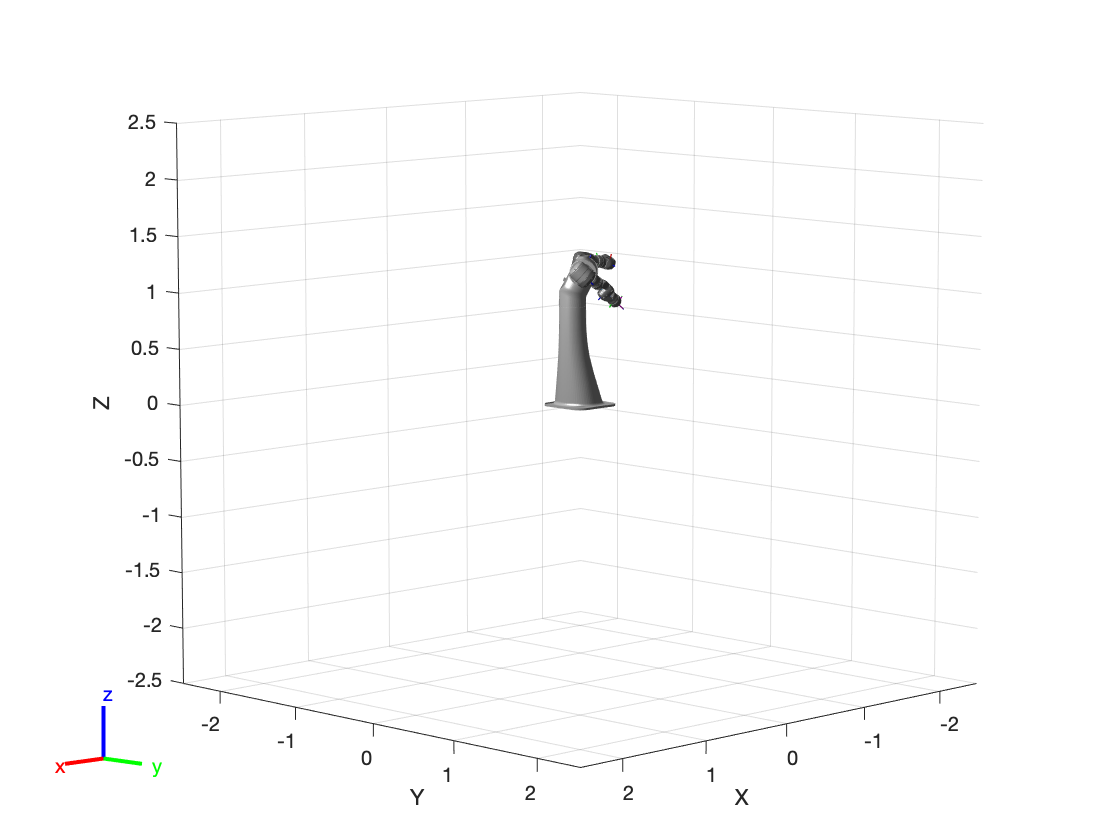

J_min_norm = 8×1
   13.6046
  -11.2538
   -4.6854
    4.3639
   -0.6901
    0.3763
  -13.1744
    0.0154


k_0 = 2.0000e-06

q_0 = 8×1
   88.0381
   88.0381
   88.0381
   88.0381
   88.0381
   88.0381
   88.0381
   88.0381


I_n = 8×8
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


Homo_sol = 8×1
   -7.3347
  -15.7111
   -0.9032
   37.6004
   -2.6447
  107.1815
   21.9022
   68.1260


theta_delta = 8×1
    6.2699
  -26.9649
   -5.5886
   41.9643
   -3.3348
  107.5578
    8.7278
   68.1414


theta = 1×8
1.0e+03 *

    2.2957    2.7129    1.9797    6.9187    1.8511    6.9263    0.5774    4.2676


epsilon_w=1;
epsilon_v=1;

% set initial omega_b and v_b
omega_b=eye(3,3)*2;
v_b=eye(3,3)*2;

%bring in robot model for animation generation.
robot = importrobot('csda10f.urdf');
robot.DataFormat='row';

%finding Moore-Penrose pseudoinverse Jacobian(J-dagger)

for i=1:100   %this is only until I figure out why it doesnt converge

% while norm(omega_b) > epsilon_w | norm(v_b) > epsilon_v
    %getting body jacobian (I currently only have space function
    M_2(i) = getframe(show(robot,[theta flip(theta)]));
    Js=J_space(omega,q,home,theta);
    FKsb=FK_space(omega,q,home,theta);
    Jb=Js_to_Jb(Js,FKsb);
    
    %testing for singularity
    if rank(Jb) ~= 6
        msg = 'singularity encountered';
        error(msg); 
    end


    %finding J-dagger 
    J_pseudo=Jb.'*((Jb*Jb.')^-1);

    %finding V
    Vb_box=logm(T_sb^-1*T_sd);
    omega_b=[Vb_box(3,2);Vb_box(1,3);Vb_box(2,1)];
    v_b=[Vb_box(1,4);Vb_box(2,4);Vb_box(3,4)];
    V=[omega_b;v_b];
    
    %define minimum norm joint velocities
    J_min_norm=J_pseudo * V

    %secondary objective function
    k_0=.000002 %realitive weight
    q_0=ones(8,1)*k_0*(sqrt(det(Jb*Jb.'))).'

    %Homogeneous solutions .... redundancy resolution .... 
    I_n=eye(8,8)
    Homo_sol=(I_n-J_pseudo*Jb)*q_0

    %calculating difference between current joint angles and
    %predicted joint angles (theta_delta)  
    theta_delta =J_min_norm+ Homo_sol
    
    %adding that difference onto the previous theta
    theta=theta+theta_delta.'
end

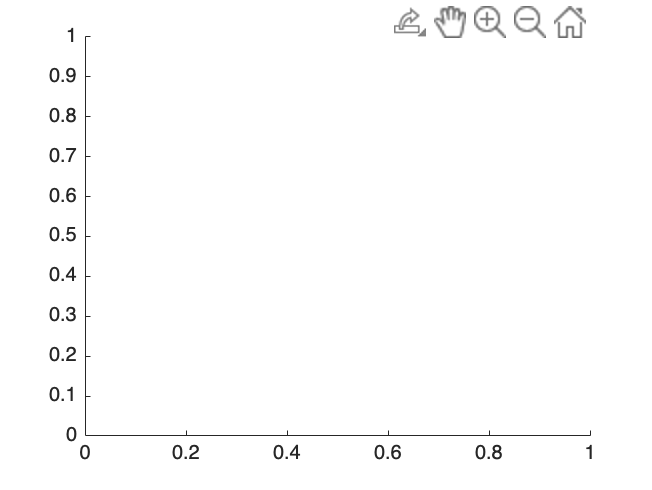

figure;
axis tight manual

movie(M_2,1,1)
